# Zhoubao Pang

# Midterm Project

# Applied Linear Control

# Spring 2019

clc;clear;close all

## Section 1

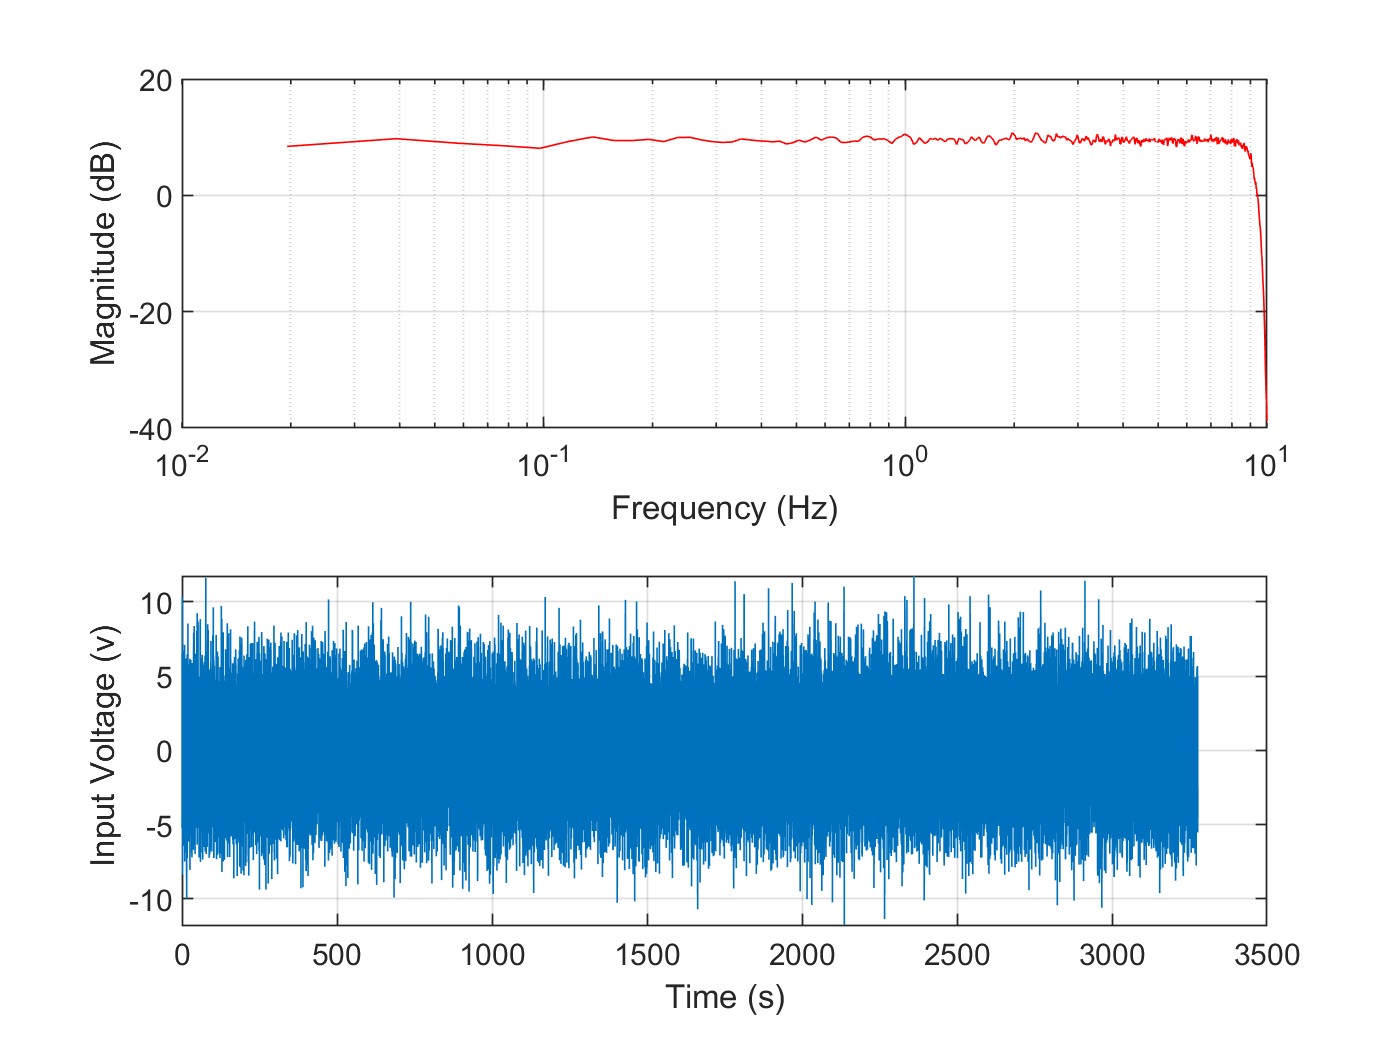

Fs = 20; %Sample rate (Hz)
Fnyq = Fs/2;
Ts = 1/Fs;
N = 2^16; % Number of sample
F = Fs / N; % frequency resolution
T = N * Ts; %total period of data
t = Ts * [0:N-1];


[b1,a1] = butter(2,[0.01 9]/(Fs/2)); %band pass filter
u = filter(b1,a1,3*randn(1,N));

u0 = zeros(1,N); %zero input

figure (1)
subplot(2,1,1)
nfft = 2^10;
wndo = nfft;
ovlp = nfft/2;
[Pxx,FR] = cpsd(u,u,wndo,ovlp,nfft,Fs);
semilogx(FR,10*log10(Pxx*Fs/2),'r')
xlim([0.01 Fs/2])
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid on
subplot(2,1,2)
plot(t,u)
xlabel('Time (s)')
ylabel(' Input Voltage (v)')
grid on

## Section 2

u10= [u;u0];
y10 = s19_plant(u10);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b
*** Warning:  Excitation saturated 34/65536 samples (0.052%)



u01= [u0;u];
y01 = s19_plant(u01);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b
*** Warning:  Excitation saturated 34/65536 samples (0.052%)


y1(1,:) = y10(1,:);
y1(2,:) = y01(1,:);
y2(1,:) = y10(2,:);
y2(2,:) = y01(2,:);

u00= [u0;u0];
yn = s19_plant(u00);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b



SNR1 = 10*log10((std(y1(1,:))^2 - std(yn(1,:))^2) / std(yn(1,:))^2) %dB

SNR1 = 46.0210

SNR2 = 10*log10((std(y2(1,:))^2 - std(yn(2,:))^2) / std(yn(2,:))^2) %dB

SNR2 = 33.5881

SNR3 = 10*log10((std(y1(2,:))^2 - std(yn(1,:))^2) / std(yn(1,:))^2) %dB

SNR3 = 40.0753

SNR4 = 10*log10((std(y2(2,:))^2 - std(yn(2,:))^2) / std(yn(2,:))^2) %dB

SNR4 = 42.6540

## Section 3

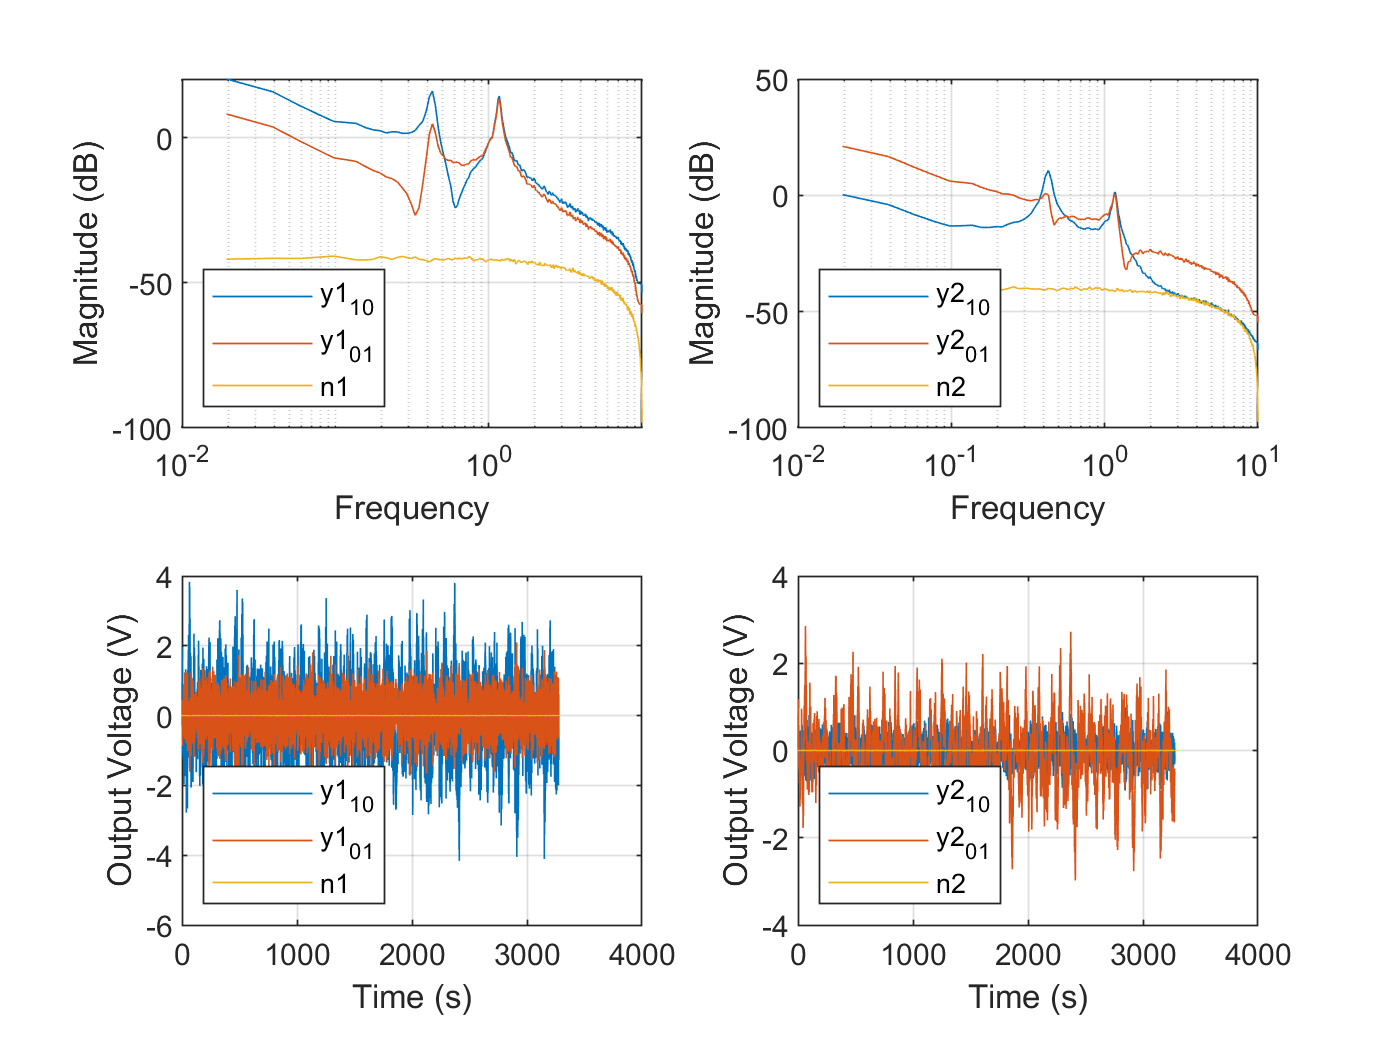

figure

[Pxxn1,FR] = pwelch(yn(1,:),wndo,ovlp,nfft,Fs);
[Pxxn2,~] = pwelch(yn(2,:),wndo,ovlp,nfft,Fs);

[Pxx1,~] = pwelch(y1(1,:),wndo,ovlp,nfft,Fs);
[Pxx2,~] = pwelch(y2(1,:),wndo,ovlp,nfft,Fs);
[Pxx3,~] = pwelch(y1(2,:),wndo,ovlp,nfft,Fs);
[Pxx4,~] = pwelch(y2(2,:),wndo,ovlp,nfft,Fs);

subplot(2,2,1)
semilogx(FR,10*log10(Pxx1*Fs/2))
hold on
semilogx(FR,10*log10(Pxx3*Fs/2))
semilogx(FR,10*log10(Pxxn1*Fs/2))
xlim([0.01 Fs/2])
xlabel('Frequency')
ylabel('Magnitude (dB)')
grid on
legend('y1_1_0','y1_0_1','n1','Location','southwest')
hold off

subplot(2,2,2)
semilogx(FR,10*log10(Pxx2*Fs/2))
hold on
semilogx(FR,10*log10(Pxx4*Fs/2))
semilogx(FR,10*log10(Pxxn2*Fs/2))
xlim([0.01 Fs/2])
xlabel('Frequency')
ylabel('Magnitude (dB)')
grid on
legend('y2_1_0','y2_0_1','n2','Location','southwest')
hold off

subplot(2,2,3)
plot(t,y1(1,:),t,y1(2,:),t,yn(1,:))
legend('y1_1_0','y1_0_1','n1','Location','southwest')
ylabel('Output Voltage (V)')
xlabel('Time (s)')
grid on

subplot(2,2,4)
plot(t,y2(1,:),t,y2(2,:),t,yn(2,:))
legend('y2_1_0','y2_0_1','n2','Location','southwest')
ylabel('Output Voltage (V)')
xlabel('Time (s)')
grid on

## Section 4

% [Suu,~] = cpsd(u,u,wndo,ovlp,nfft,Fs);
% [Suy,~] = cpsd(y1(1,:),u,wndo,ovlp,nfft,Fs);
% H1 = Suy./Suu;

[H1(:,1),~] = tfestimate(u,y1(1,:),wndo,ovlp,nfft,Fs);
[H1(:,2),~] = tfestimate(u,y2(1,:),wndo,ovlp,nfft,Fs);
[H1(:,3),~] = tfestimate(u,y1(2,:),wndo,ovlp,nfft,Fs);
[H1(:,4),~] = tfestimate(u,y2(2,:),wndo,ovlp,nfft,Fs);
gamma(:,1) = mscohere(u,y1(1,:),wndo,ovlp,nfft,Fs);
gamma(:,2) = mscohere(u,y2(1,:),wndo,ovlp,nfft,Fs);
gamma(:,3) = mscohere(u,y1(2,:),wndo,ovlp,nfft,Fs);
gamma(:,4) = mscohere(u,y2(2,:),wndo,ovlp,nfft,Fs);

% figure
% plot(FR,gamma1)
% hold on 
% plot(FR,gamma2)
% plot(FR,gamma3)
% plot(FR,gamma4)
% hold off

## Section 5

Nb = 2; %number of poles
Na(1) = 2; %number of zeros
Na(2) = 2; %number of zeros
Na(3) = 2; %number of zeros
Na(4) = 2; %number of zeros

[k,~] = size(H1);
fr = logspace(-2,1,k);
% TODO: remove integrator and add them back in. See L11
% Hinte = freqs([1], [1 0], 2*pi*FR);
% H1_1_new = H1_1./ Hinte;
%invfreqz
% a1 = [a1, 0];

inte_s = tf([1], [1 0]);
inte_z = c2d(inte_s,Ts,'Tustin');
% inte_z = c2d(inte_s,Ts,'zoh');
b_inte = cell2mat(inte_z.Numerator);
a_inte = cell2mat(inte_z.Denominator);
Hinte = freqz(b_inte,a_inte,length(FR));

k = 1;
for m = 1:2
    for p = 1:2
        H1_wo_inte = H1(:,k)./Hinte;
        [num, den] = invfreqz(H1_wo_inte,(pi*fr)/(Fs/2),Nb,Na(k));
%         [num, den] = invfreqz(H1(:,k),(pi*FR)/(Fs/2),Nb,Na(k));
%         den = [den, 0]; %add integrator back (IS THIS RIGHT?)
        NUM{p,m,:} = num;
        DEN{p,m,:} = den;
        k = k + 1;
    end
end
Htf = tf(NUM,DEN,Ts) * inte_z; %(add integrator back)
% Htf = tf(NUM,DEN,Ts); 
Hmr = minreal(Htf);

## Section 6

State-space realization

Hss = ss(Hmr); 

Balanced realization

[Hbr, Hsv] = balreal(Hss); % [balance realization, hankel singular values]

Number of states

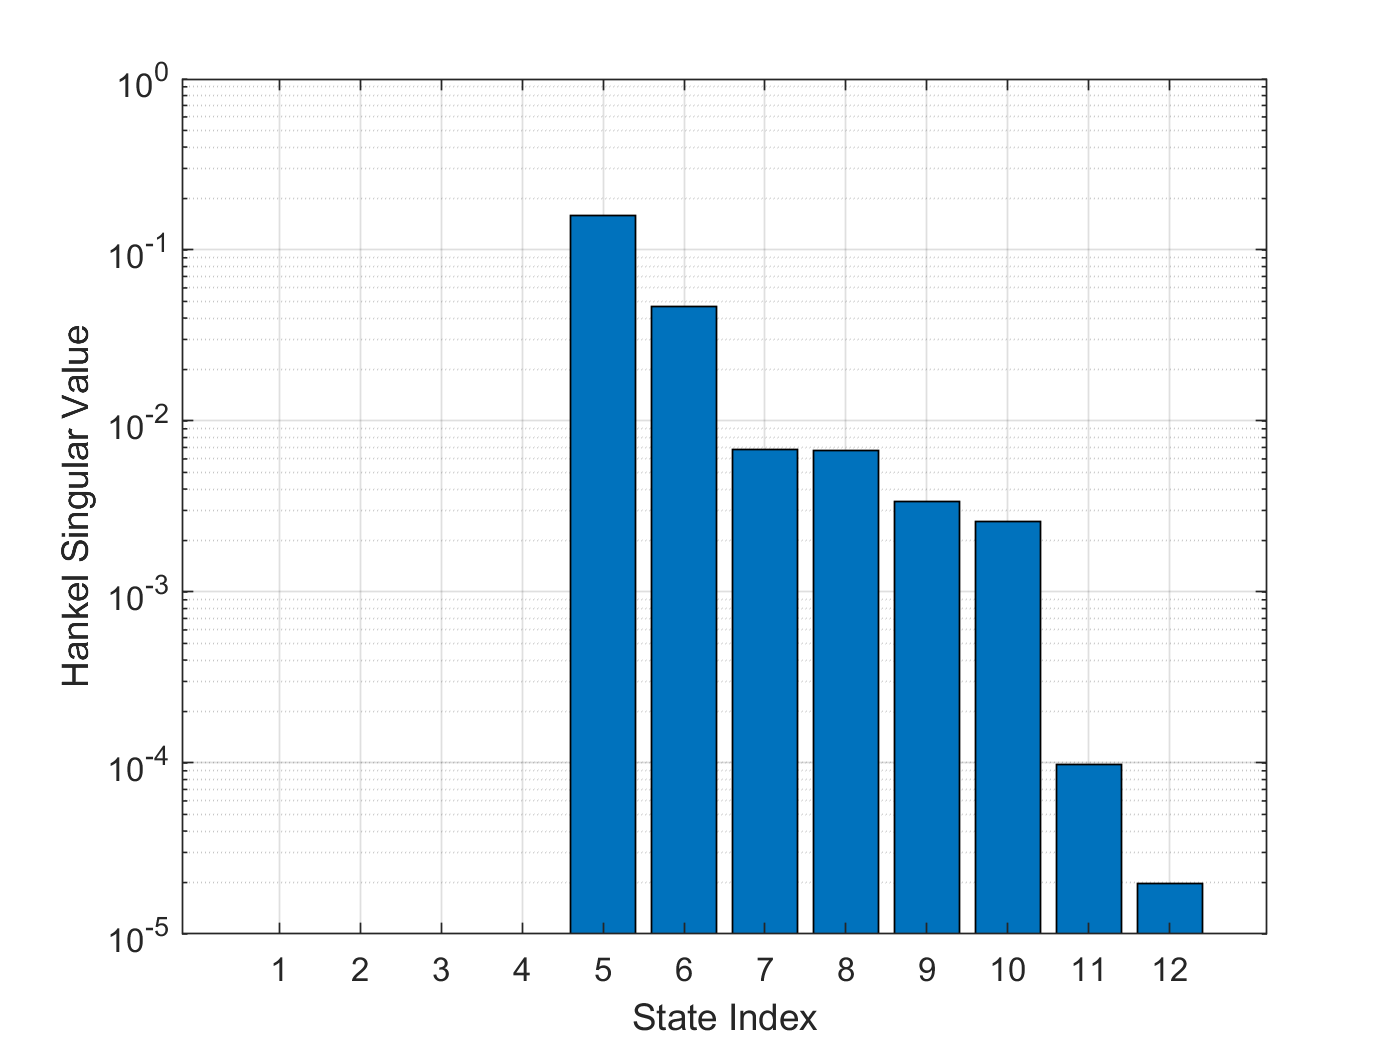

NFIT = size(Hbr.A,1); % extract number of rows of A matrix
figure
bar([1:NFIT],Hsv)
grid on
set(gca,'yscale','log')
ylabel('Hankel Singular Value')
xlabel('State Index')

Cutoff_HSV = 1E0; %based on visual inspection of the bar chart
elim = (Hsv < Cutoff_HSV);
Hss_red = modred(Hss,elim,'Truncate');

## Section 7

Poles = pole(Hss_red);
Zeros = tzero(Hss_red);
[Wn, zeta] = damp(Hss_red);
Natural_Frequency_Hz = Wn / (2*pi);
T = table(Poles,Natural_Frequency_Hz,zeta);
disp(T)

     Poles     Natural_Frequency_Hz       zeta   
    _______    ____________________    __________

    -0.9993         7.0679e-16                 -1
          1            0.17234                  1
    0.88091            0.40361                  1
     0.9473                 10         0.00022375



## Section 8

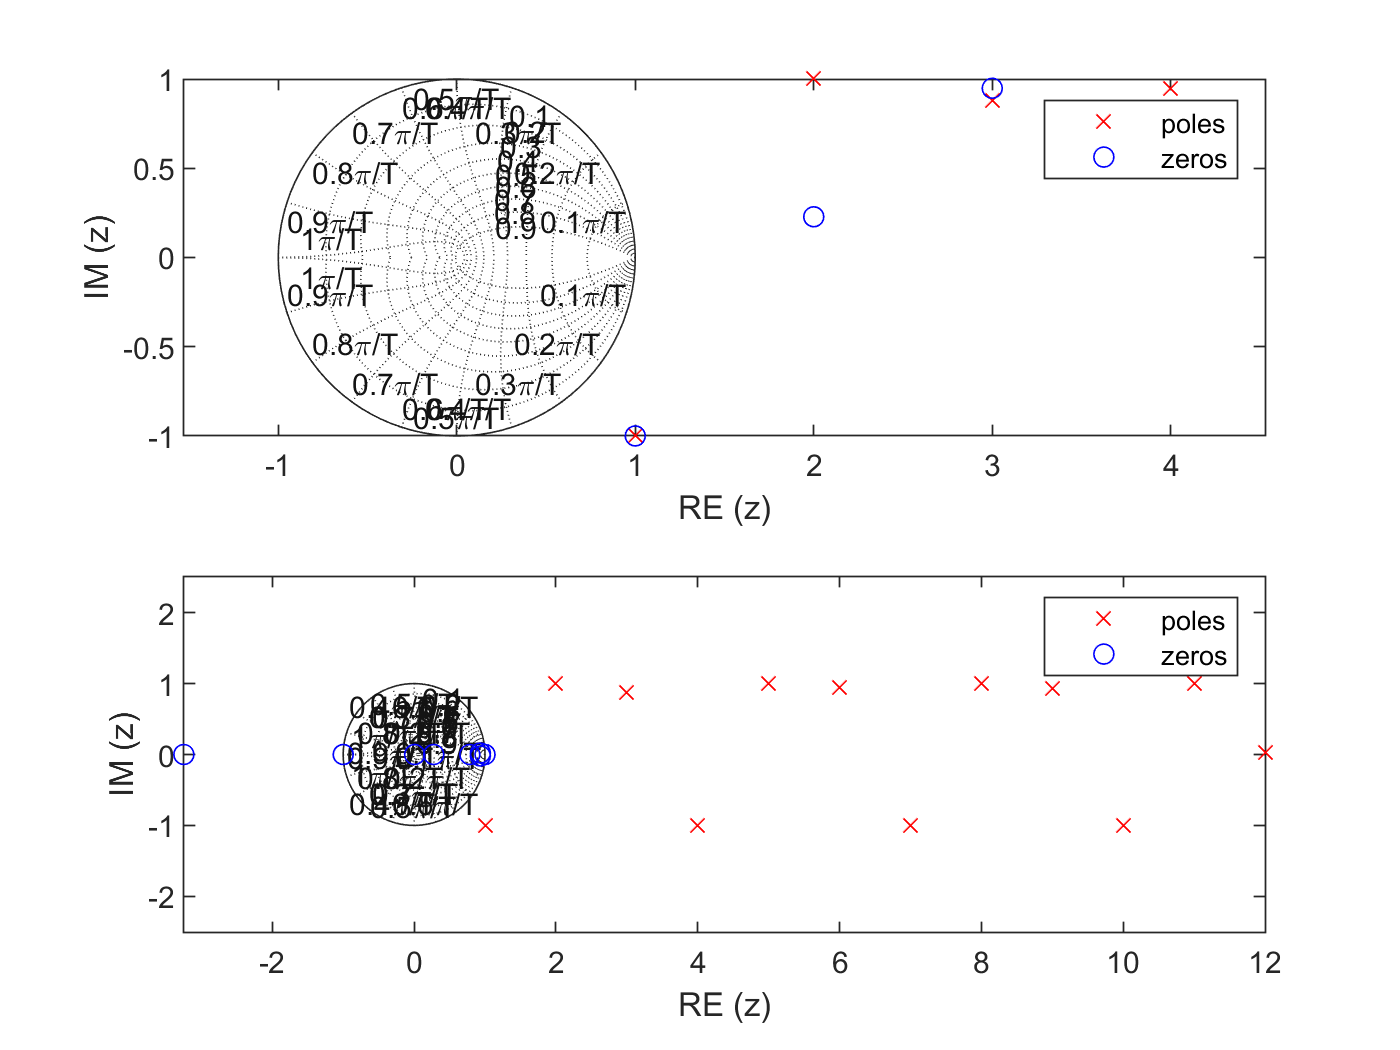

figure
subplot(2,1,1)
plot(pole(Hss_red),'x','Color','r')
hold on
plot(tzero(Hss_red),'o','Color','b')
hold off
legend('poles','zeros','AutoUpdate','off')
zgrid
axis equal
xlabel('RE (z)')
ylabel('IM (z)')

subplot(2,1,2)
plot(pole(Htf),'x','Color','r')
hold on
plot(tzero(Htf),'o','Color','b')
hold off
legend('poles','zeros','AutoUpdate','off')
zgrid
axis equal
xlabel('RE (z)')
ylabel('IM (z)')

## Section 9

FreqResp_5 = squeeze(freqresp(Htf,2*pi*FR)); % complex FRF vector

Ph5 = (180/pi)*angle(FreqResp_5);
Mag5 = 20*log10(abs(FreqResp_5));

FreqResp_6 = squeeze(freqresp(Hss_red,2*pi*FR)); % complex FRF vector

Ph6 = (180/pi)*angle(FreqResp_6);
Mag6 = 20*log10(abs(FreqResp_6));

## Section 10

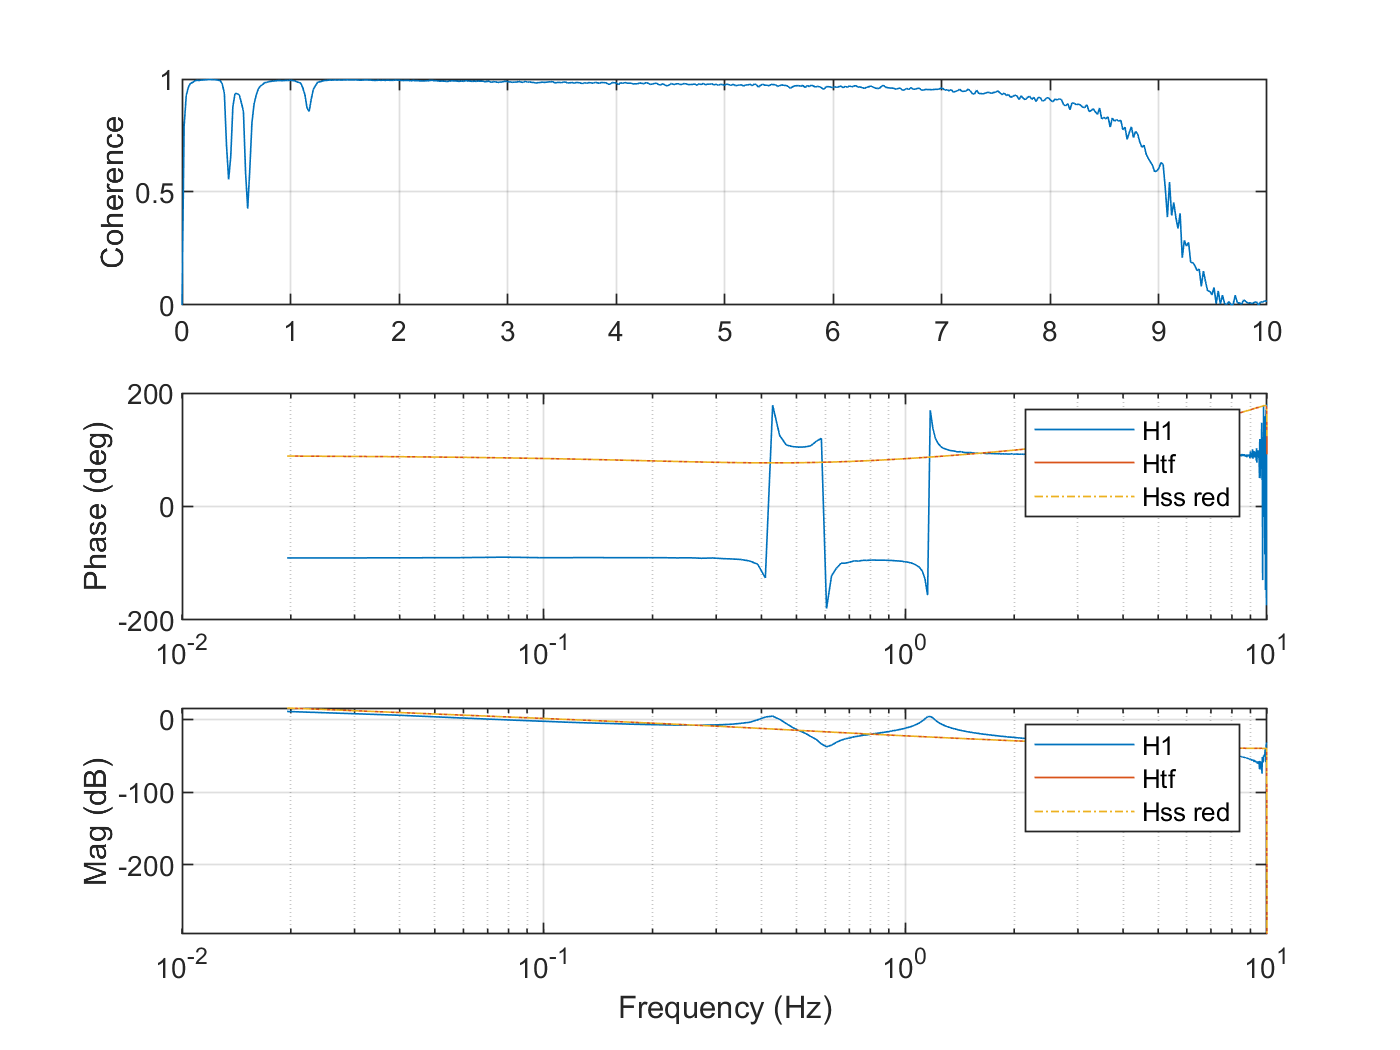

Ph4_1 = (180/pi)*angle(H1(:,1));
Mag4_1 = 20*log10(abs(H1(:,1)));
figure
subplot(3,1,1)
plot(FR,gamma(:,1))
grid on
ylabel('Coherence')
subplot(3,1,2)
semilogx(FR,Ph4_1,FR,squeeze(Ph5(1,1,:)),FR,squeeze(Ph6(1,1,:)),'-.');
legend('H1','Htf','Hss red')
ylabel('Phase (deg)')
grid on
subplot(3,1,3)
semilogx(FR,Mag4_1,FR,squeeze(Mag5(1,1,:)),FR,squeeze(Mag6(1,1,:)),'-.');
ylabel('Mag (dB)')
xlabel('Frequency (Hz)')
legend('H1','Htf','Hss red')
grid on

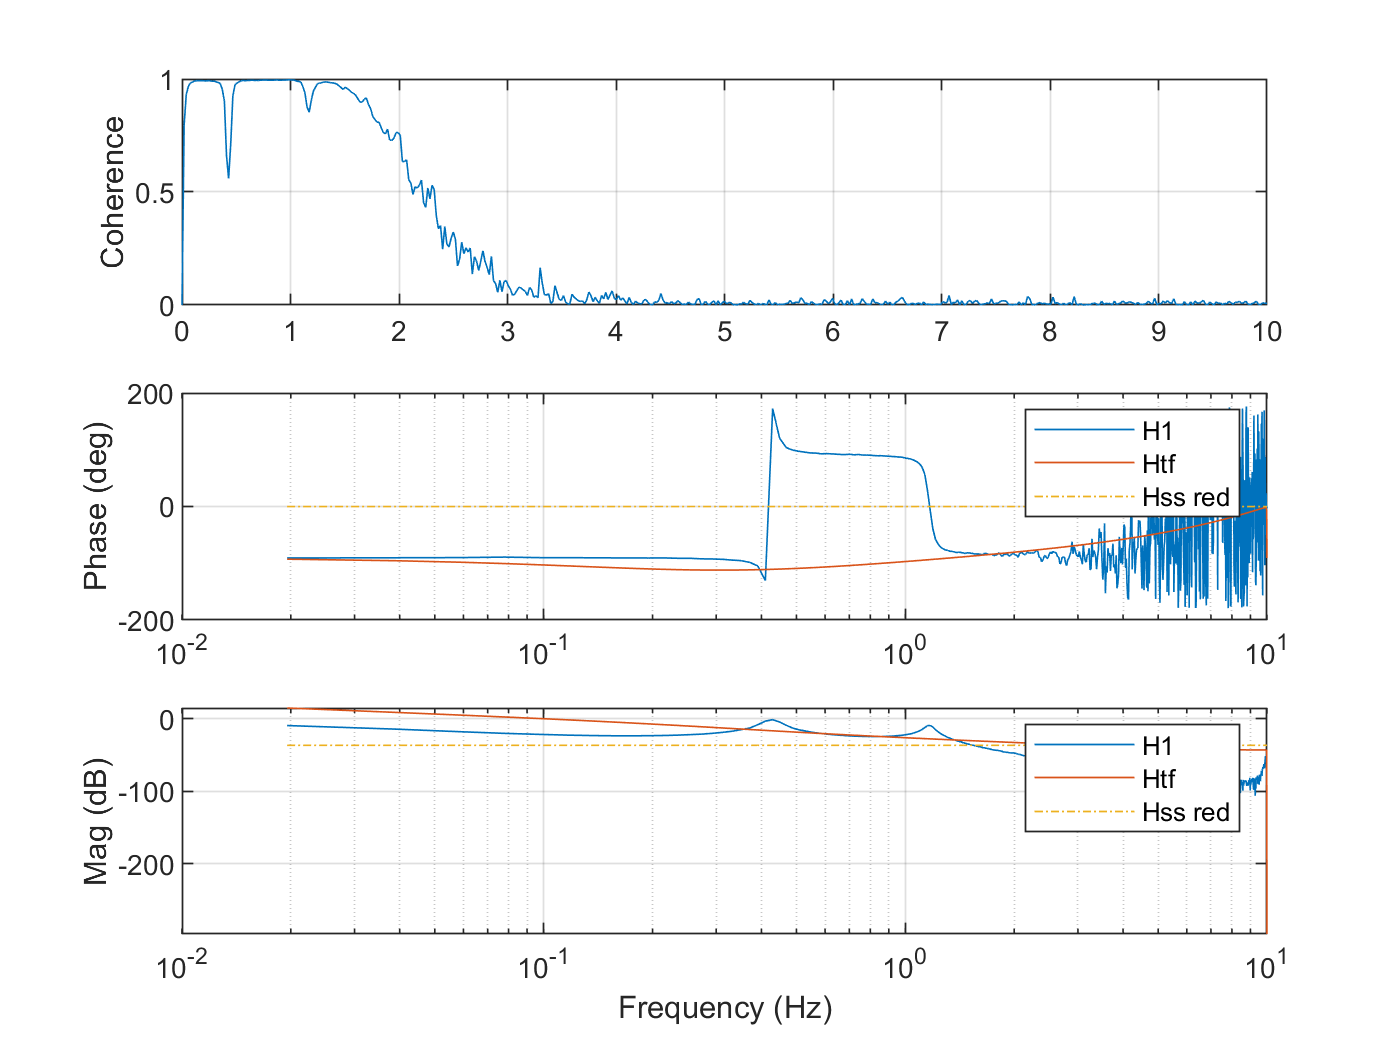

Ph4_2 = (180/pi)*angle(H1(:,2));
Mag4_2 = 20*log10(abs(H1(:,2)));
figure
subplot(3,1,1)
plot(FR,gamma(:,2))
grid on
ylabel('Coherence')
subplot(3,1,2)
semilogx(FR,Ph4_2,FR,squeeze(Ph5(1,2,:)),FR,squeeze(Ph6(1,2,:)),'-.');
legend('H1','Htf','Hss red')
ylabel('Phase (deg)')
grid on
subplot(3,1,3)
semilogx(FR,Mag4_2,FR,squeeze(Mag5(1,2,:)),FR,squeeze(Mag6(1,2,:)),'-.');
ylabel('Mag (dB)')
xlabel('Frequency (Hz)')
legend('H1','Htf','Hss red')
grid on

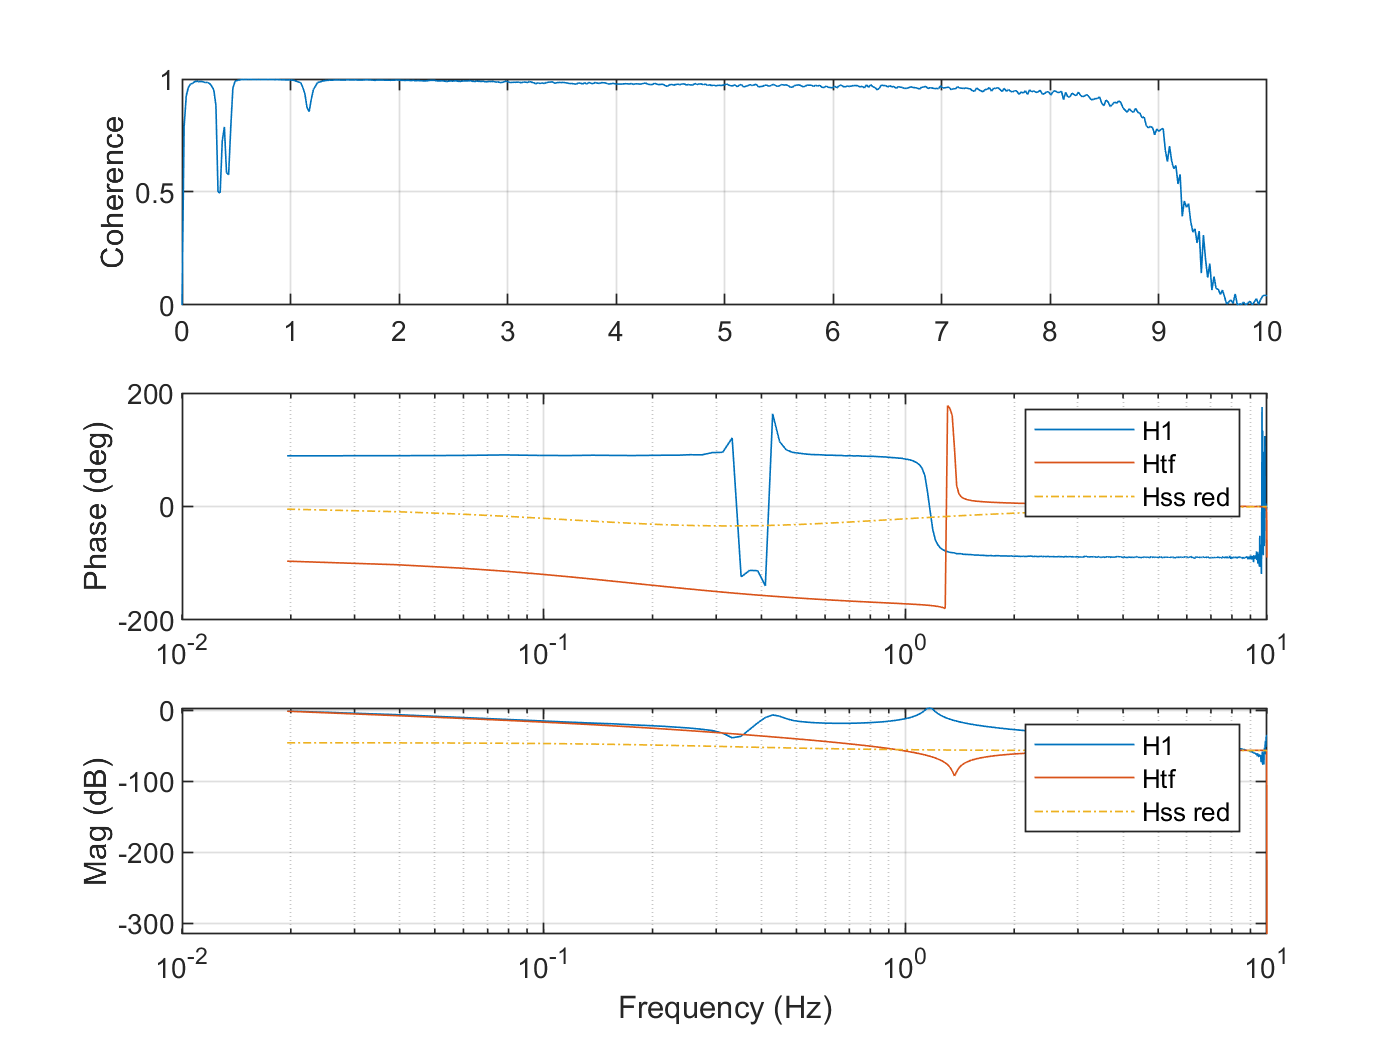

Ph4_3 = (180/pi)*angle(H1(:,3));
Mag4_3 = 20*log10(abs(H1(:,3)));
figure
subplot(3,1,1)
plot(FR,gamma(:,3))
grid on
ylabel('Coherence')
subplot(3,1,2)
semilogx(FR,Ph4_3,FR,squeeze(Ph5(2,1,:)),FR,squeeze(Ph6(2,1,:)),'-.');
legend('H1','Htf','Hss red')
ylabel('Phase (deg)')
grid on
subplot(3,1,3)
semilogx(FR,Mag4_3,FR,squeeze(Mag5(2,1,:)),FR,squeeze(Mag6(2,1,:)),'-.');
ylabel('Mag (dB)')
xlabel('Frequency (Hz)')
legend('H1','Htf','Hss red')
grid on

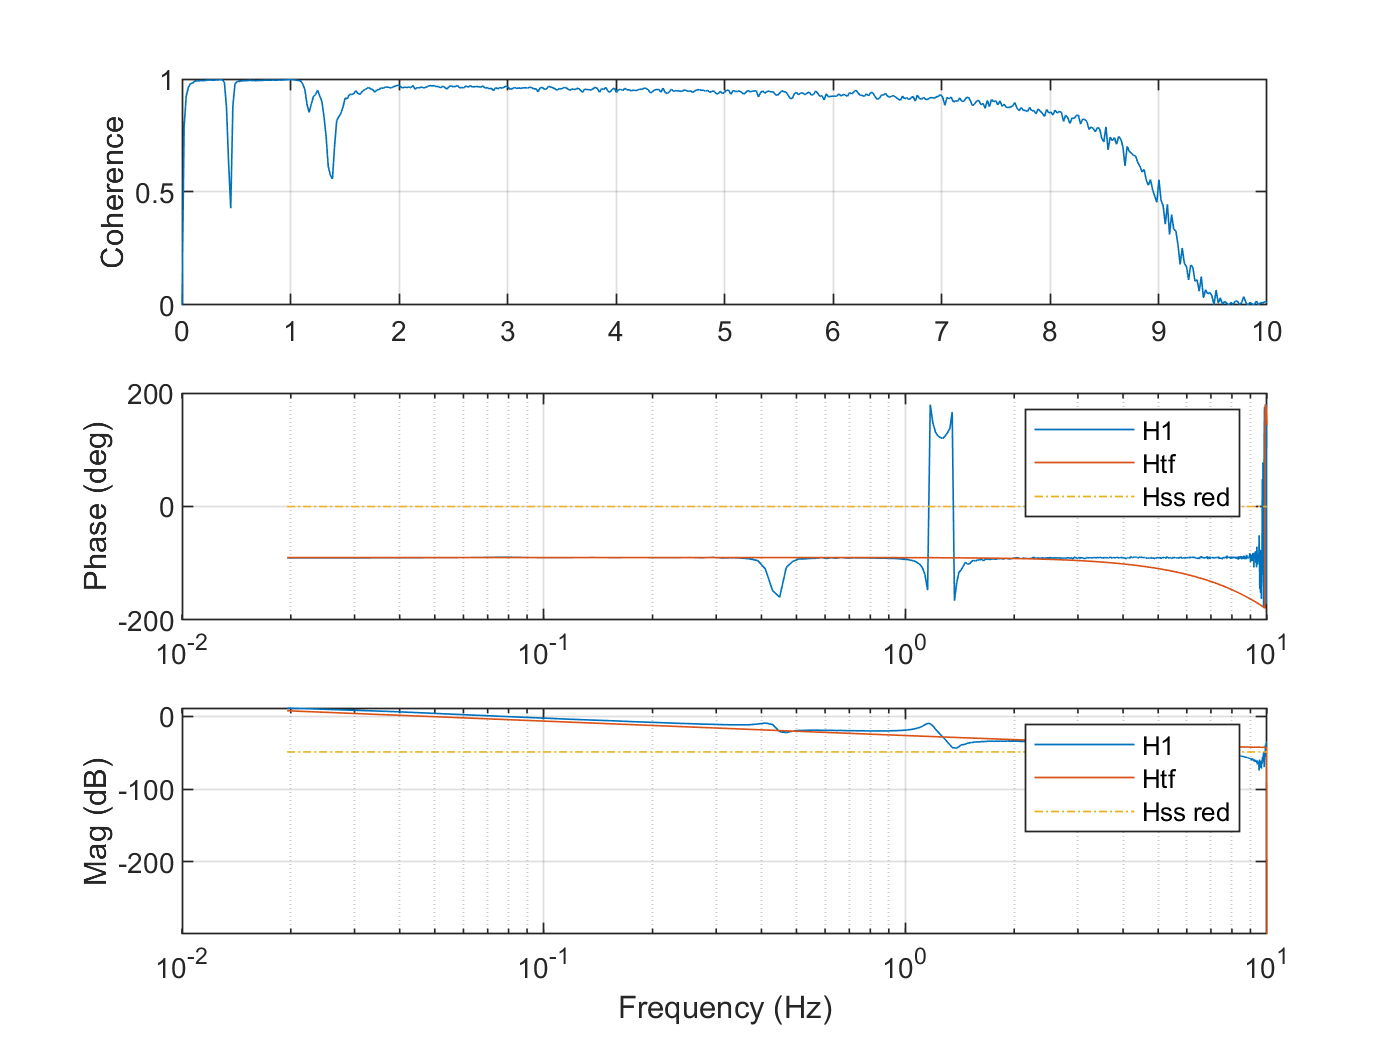

Ph4_4 = (180/pi)*angle(H1(:,4));
Mag4_4 = 20*log10(abs(H1(:,4)));
figure
subplot(3,1,1)
plot(FR,gamma(:,4))
grid on
ylabel('Coherence')
subplot(3,1,2)
semilogx(FR,Ph4_4,FR,squeeze(Ph5(2,2,:)),FR,squeeze(Ph6(2,2,:)),'-.');
legend('H1','Htf','Hss red')
ylabel('Phase (deg)')
grid on
subplot(3,1,3)
semilogx(FR,Mag4_4,FR,squeeze(Mag5(2,2,:)),FR,squeeze(Mag6(2,2,:)),'-.');
ylabel('Mag (dB)')
xlabel('Frequency (Hz)')
legend('H1','Htf','Hss red')
grid on